# Excersize 6

Given a cable robot with 2 dof, evaluate the manipulability.

- Create the direct and inverse kinematics

- Evaluate the manipulability

- Optional UI

We assume a fixed lenght cable.

clear all;
clc;

L = 10;

r = 2; % radious of the 'rocchetto'

PE = [5; -5];

q = ik(PE(1), PE(2), r, L);

rad2deg(q(1))

ans = 202.5712

rad2deg(q(2))

ans = 202.5712


fk(q(1), q(2), r, L)

ans =     5.0000
   -5.0000



A = jac(q(1), q(2), 2, 10)

A =     1.4142   -1.4142
   -1.4142   -1.4142


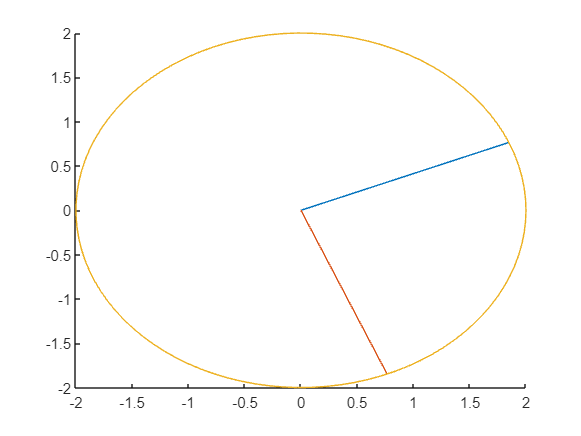

C = [0, 0]; % center of the ellipse in reality in the gui is the point on which we calculate the inverse kinematics

t = linspace(0, 2*pi, 100);

[vec, val] = eig(A);

eigs = sort([val(1, 1) val(2, 2)], 'descend');

theta1 = atan2(vec(2, 2), vec(2, 1));
theta2 = atan2(vec(1, 2), vec(1, 1));

x = C(1) + eigs(1)*cos(t);
y = C(2) + eigs(2)*sin(t);

hold on;
plot([C(1), val(1, 1)*cos(theta1)], [C(2), val(2, 2)*sin(theta1)])
plot([C(1), val(1, 1)*cos(theta2)], [C(2), val(2, 2)*sin(theta2)])
plot(x, y);
hold off;

Beginning of the loop
End of the loop

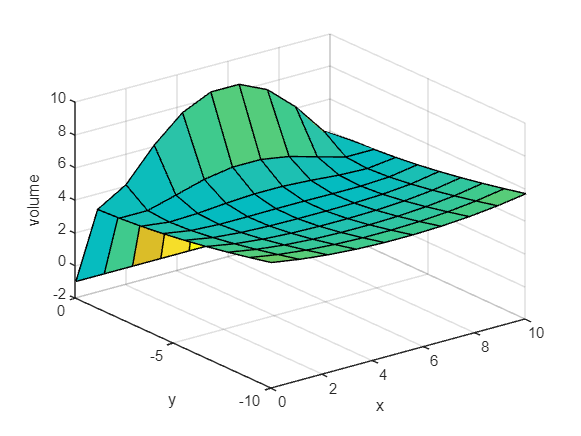

mapVolume(10, r, L);

function mapVolume(dim, r, L)
    x = 0:L/(dim-1):L;
    y = -L:L/(dim-1):0;

    [v, s] = meshgrid(x, y);
    
    tuples = [v(:) s(:)];

    volumes = -1*ones(length(tuples), 1);

    fprintf('Beginning of the loop\n');

    for i=1:length(tuples)
        vec = tuples(i, :);
        try
            q = ik(vec(1), vec(2), r, L);
            J = jac(q(1), q(2), r, L);
            volumes(i) = sqrt(det(J*J'));
        catch
            volumes(i) = -1;
        end
    end
    fprintf('End of the loop');

    volumes = reshape(volumes, [], cast(sqrt(length(tuples)), "uint32"));

    clf;
    surf(v, s, volumes);
    xlabel('x');
    ylabel('y');
    zlabel('volume');
end

function mjac = jac(q1, q2, r, L) % jacobian calculation
    q = sym('q_%d',[1 2]);
    
    l1 = q(1)*r;
    l2 = q(2)*r;
    x = (L^2 + l1^2 - l2^2)/(2*L);
    fvec = [x;
            -sqrt((l1^2 - x^2))
           ];
    mjac = double(subs(jacobian(fvec, q), q, [q1, q2]));
end

function fvec = fk(q1, q2, r, L) % forward kinematics
    l1 = q1*r;
    l2 = q2*r;
    x = (L^2 + l1^2 - l2^2)/(2*L);
    fvec = [x;
            -sqrt((l1^2 - x^2))
           ];
end

function ivec = ik(x, y, r, L) % inverse kinematics
    ivec = [sqrt((x^2 + y^2))/r;
            sqrt(((L - x)^2 + y^2))/r
           ];
end